# **Figure 9**

This m-file is written according  to  the paper entitled :

 "**An Efficient Low-Complexity Method to Calculate Hybrid Beamforming Matrices for mmWave Massive MIMO Systems**" 

you can see the paper on this link:  [https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813)

## **Authors: **

**1- Jamal Beiranvand** 

    Website: 

    e-mail: Jamalbeiranvand@gmail.com

    google scholar:  [https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en](https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en)

2- **Vahid Meghdadi**

    website: [https://www.unilim.fr/pages_perso/vahid/](https://www.unilim.fr/pages_perso/vahid/) 

    e-mail: meghdadi@ensil.unilim.fr

    google scholar:  [https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en](https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en)

## Required Functions to run

All functions used in this code are in the** "Functions" **folder, described in the **"MATLAB Functions" **document.

**Note: **change  the path of **Functions** folder according its path in your PC.

Date : 02/07/2021

By Jamal Beiranvand

## Initialize

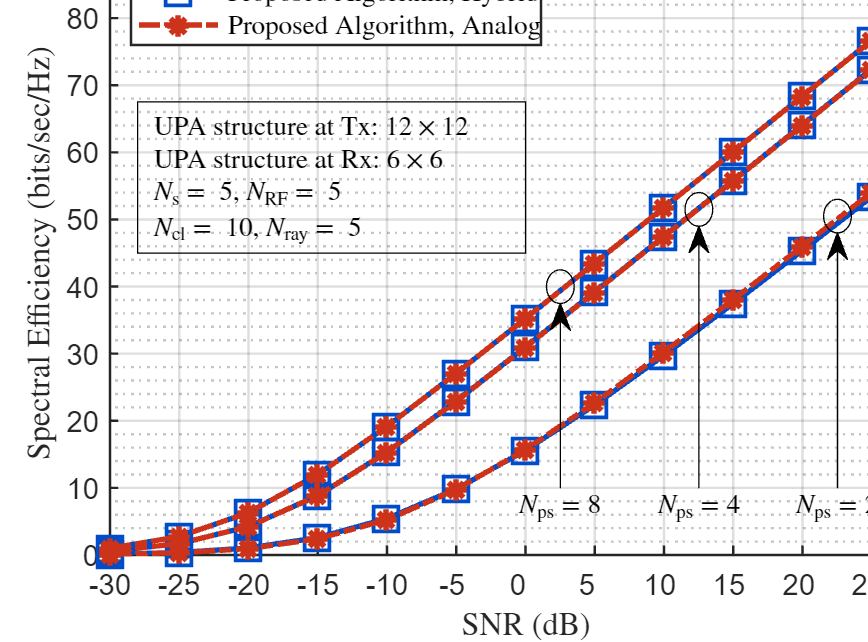

clear;
clc
warning off
%% User pannel Parameters (you may have to change some values in the "Plot" section)
addpath(genpath('C:\Users\Jamal\OneDrive\Jamal\MATLAB Code\Functions') ) % Add path of the "Functions" folder.
Nps = [2 4 8];                 % Number of the Fixed phase Shifters
Txz = 12;                      % Number of the transmitter antennas on z axis
Txy = 12;                      % Number of the transmitter antennas on y axis
Rxz = 6;                       % Number of the receiver antennas on z axis
Rxy = 6;                       % Number of the receiver antennas on y axis
Ns  = 5;                       % Number of data streams
NRF = Ns;                      % Number of RF chains
Ncl =10;                       % Number of Channel clusters(Scatters)
Nray= 5;                       % Number of rays in each cluster
AngSpread = 10;       % Angle spread, standard deviation of the angles in azimuth and elevation both of Rx and Tx
SNR_dB = -30:5:30;             % Signal to noise ratio in dB
realization = 300;             % Iteration of simulation

%% Initialize Parameters
Tx  = [Txz,Txy];               % Srtucture of the transmit antanna array
Rx  = [Rxz,Rxy];               % Srtucture of the receiver antanna array 
Nt  = Txz*Txy;                 % Number of the transmit antennas
Nr  = Rxz*Rxy;                 % Number of the receive antennas
SNR = 10.^(SNR_dB./10);
%% Allocate memory space for matrices
R_Nov=zeros(length(SNR_dB),realization); 
R_Nova=zeros(length(SNR_dB),realization);
R_Dig=zeros(length(SNR_dB),realization);

Data1=zeros(length(SNR_dB),length(Nps));
Data2=zeros(length(SNR_dB),length(Nps));
Data3=zeros(length(SNR_dB),length(Nps));
%Main Code
%% Main Code
for n=1:length(Nps)   
    % Generate basis set and switches states
    [~,~,Setb,Sb]=GenUniqueSet(Nps(n));
%     [Setb,Sb]=GenUniqueSet(Nps(n));
    for reali=1:realization
        
        % generate channel
        [H,At,Ar,alpha]=Channel(Tx,Rx,Ncl,'Nray',Nray,'AngSpread',AngSpread);
        
        % Full Digital beamforming
        [W_Dig,F_Dig]=DigitalBeamforming(H,Ns);
        
        % Novel Algorithm
        [WRF_Nov,WBB_Nov,FRF_Nov,FBB_Nov] = NovelAlg(H,Ns,Setb,Sb);
        FBB_Nov =  FBB_Nov / norm(FRF_Nov * FBB_Nov,'fro');        % Analog Novel
       
        Fa=  FRF_Nov / norm(FRF_Nov,'fro');
        Wa=  WRF_Nov / norm(WRF_Nov,'fro');
        
          for r=1:length(SNR)
            R_Nov(r,reali) = log2(det(eye(Ns) + SNR(r) * pinv(WRF_Nov * WBB_Nov)  * H * FRF_Nov * FBB_Nov * (FBB_Nov)' * FRF_Nov' * H' * WRF_Nov * WBB_Nov));
            R_Nova(r,reali) = log2(det(eye(Ns)+ SNR(r) * pinv(Wa)     * H * Fa     * (Fa)'     * H' * Wa)); 
            R_Dig(r,reali) = log2(det(eye(Ns) + SNR(r)*  pinv(W_Dig)  * H * F_Dig  * (F_Dig)'  * H' * W_Dig));
          end
    end
    Data1(:,n)= sum((R_Dig),2)/realization;
    Data2(:,n)= sum(R_Nov,2)/realization;
    Data3(:,n)= sum(R_Nova,2)/realization;
end
%Plot
% prepare data to plot
Xaxis=SNR_dB;
%% plot 
Fig=figure;
hold on
% P1=plot(Xaxis,Data1(:,1));
P2=plot(Xaxis,Data2);
P3=plot(Xaxis,Data3);
% P4=plot(Xaxis,Data4);
% P5=plot(Xaxis,Data5);

% Legend1='Optimal Digital Beamforming';
Legend2='Proposed Algorithm, Hybrid';
Legend3='Proposed Algorithm, Analog';
% Legend4='DPS structure';
% Legend5='PE-AltMin Algorithm';
% Legend3=('Data1 $N_t=144$, $Nr=36$');

% % P1 properties
% set(P1,'LineStyle','-');           % '-' , '--' , ':' , '-.' , 'none'
% set(P1,'Marker','none');       % 'o' , '+'  , '*' , 'x' ,'s' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram', 'none'
% set(P1,'LineWidth',3);
% set(P1,'Color','g');
% set(P1,'MarkerSize',10);
% P1_group= hggroup;set(P1,'Parent',P1_group);
% set(get(get(P1_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on'); 
% P1.MarkerIndices =[ 1 6];

% P2 properties
set(P2,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P2,'Marker','s');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P2,'LineWidth',2);
set(P2,'Color',[0 .3 .8]);
set(P2,'MarkerSize',12);
P2_group= hggroup;set(P2,'Parent',P2_group);
set(get(get(P2_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

% % P2 properties
set(P3,'LineStyle','-.');           % '-' , '--' , ':' , '-.'
set(P3,'Marker','*');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P3,'LineWidth',2);
set(P3,'Color',[.8 .2 .1]);
set(P3,'MarkerSize',8);
P3_group= hggroup;set(P3,'Parent',P3_group);
set(get(get(P3_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% % 
% % P2 properties
% set(P4,'LineStyle','-');           % '-' , '--' , ':' , '-.'
% set(P4,'Marker','hexagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
% set(P4,'LineWidth',2);
% set(P4,'Color',[.8 .5 0]);
% set(P4,'MarkerSize',7);
% P4_group= hggroup;set(P4,'Parent',P4_group);
% set(get(get(P4_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% % P2 properties
% set(P5,'LineStyle','--');           % '-' , '--' , ':' , '-.'
% set(P5,'Marker','x');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
% set(P5,'LineWidth',2);
% set(P5,'Color',[.8 .5 .5]);
% set(P5,'MarkerSize',7);
% P5_group= hggroup;set(P5,'Parent',P5_group);
% set(get(get(P5_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 

lgd=legend(Legend2,Legend3);
% Axes Properties 
ax=gca;
ax.XLim = [min(Xaxis) max(Xaxis)];
% ax.YLim = [5 40];
ax.XTick = Xaxis;
ax.XTickLabel=Xaxis;
ax.XLabel.String='SNR (dB)';
ax.YLabel.String='Spectral Efficiency (bits/sec/Hz)';
ax.XGrid='on';
ax.YGrid='on';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.YLabel.Interpreter='latex';
ax.XLabel.Interpreter='latex';
ax.FontSize = 11;
ax.LineWidth = .9;
ax.Box='on';

% Legend Properties %
lgd.Location= 'northwest'; %%
lgd.Box='on';
lgd.LineWidth=.9;
lgd.Interpreter='latex';
lgd.FontSize = 10;
% 
% Figure Properties
ax.Units='centimeters';
ax.Position = [ax.TightInset(1)+ax.TightInset(3) ax.TightInset(2) 11 8];
Fig.Units='centimeters';
Fig.Position = [10 5 (ax.TightInset(1)+ 2*ax.TightInset(3)+ ax.Position(3) ) (ax.TightInset(2)+ ax.TightInset(4)+ ax.Position(4))];

%  Creat notation 
Not1=annotation('textbox');
X_points=[-28 0];
Y_points=[ .5*(diff(ax.YLim)) .75*(diff(ax.YLim))];
str1=['UPA structure at Tx: ',num2str(Tx(1)),'$\times$',num2str(Tx(2))];
str2=['UPA structure at Rx: ',num2str(Rx(1)),'$\times$',num2str(Rx(2))];
str3=['$N_{\mathrm{s}}=$ ',num2str(Ns),',  $N_{\mathrm{RF}}=$ ',num2str(NRF)];
str4=['$N_{\mathrm{cl}}=$ ',num2str(Ncl),',  $N_{\mathrm{ray}}=$ ',num2str(Nray)];
Not1.String={str1,str2,str3,str4};
Not1.FontSize = 10;
Not1.Interpreter='latex';
Not1.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Not1.Position=[x_begin y_begin  x_End y_End];
% % % % 
% % 
Ell=annotation('ellipse');
X_points=[1.5 3.5];
Y_points=[37.5 42.5];
Ell.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Ell.Position=[x_begin y_begin  x_End y_End];
% 
Textarrow1=annotation('textarrow');
X_points=[2.5 2.5];
Y_points=[10 37.5];
str1=['$N_{\mathrm{ps}}=$',num2str(Nps(3))];
Textarrow1.String={str1};
Textarrow1.Interpreter='latex';
Textarrow1.FontSize = 10;
Textarrow1.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Textarrow1.Position=[x_begin y_begin  x_End y_End];
% %%
Ell2=annotation('ellipse');
X_points=[11.5 13.5];
Y_points=[49 54];
Ell2.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Ell2.Position=[x_begin y_begin  x_End y_End];
% 
Textarrow2=annotation('textarrow');
X_points=[12.5 12.5];
Y_points=[10 49];
str1=['$N_{\mathrm{ps}}=$',num2str(Nps(2))];
Textarrow2.String={str1};
Textarrow2.Interpreter='latex';
Textarrow2.FontSize = 10;
Textarrow2.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Textarrow2.Position=[x_begin y_begin  x_End y_End];
% %%
Ell3=annotation('ellipse');
X_points=[21.5 23.5];
Y_points=[48 53];
Ell3.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Ell3.Position=[x_begin y_begin  x_End y_End];
% 
Textarrow3=annotation('textarrow');
X_points=[22.5 22.5];
Y_points=[10 48];
str1=['$N_{\mathrm{ps}}=$',num2str(Nps(1))];
Textarrow3.String={str1};
Textarrow3.Interpreter='latex';
Textarrow3.FontSize = 10;
Textarrow3.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Textarrow3.Position=[x_begin y_begin  x_End y_End];